Running k-Wave simulation...
  start time: 28-Apr-2023 13:15:21
  reference sound speed: 1500m/s
  dt: 78.125ns, t_end: 57.7344us, time steps: 740
  input grid size: 128 by 128 grid points (50 by 50mm)
  maximum supported frequency: 1.92MHz
  expanding computational grid...
  computational grid size: 168 by 168 grid points
  precomputation completed in 0.11778s
  starting time loop...
  estimated simulation time 17.76s...


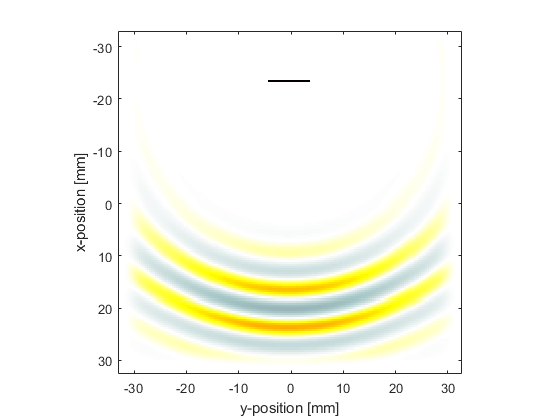

  simulation completed in 16.6103s
  total computation time 16.761s


clearvars;

% create the computational grid
Nx = 128;           % number of grid points in the x (row) direction
Ny = Nx;            % number of grid points in the y (column) direction
dx = 50e-3/Nx;    	% grid point spacing in the x direction [m]
dy = dx;            % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);


% kgrid.dt = 7.3242e-8;

% define the properties of the propagation medium
medium.sound_speed = 1500;  % [m/s]
medium.alpha_coeff = 0.75;  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;

% create the time array
kgrid.makeTime(medium.sound_speed);

kgrid.Nt = 740;

num_elements = 21;
source.p_mask = zeros(Nx, Ny);
x_offset = 5;
y_offset = 20;
start_index = Ny/2 - round(num_elements/2) + 1;
source.p_mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% define the properties of the tone burst
sampling_freq = 1/kgrid.dt;     % [Hz]
steering_angle = 0;            % [deg]
element_spacing = dx;           % [m]
tone_burst_freq = 2e5;          % [Hz]
tone_burst_cycles = 5;

% create an element index relative to the centre element of the transducer
element_index = -(num_elements - 1)/2:(num_elements - 1)/2;

% use geometric beam forming to calculate the tone burst offsets for each
% transducer element based on the element index
tone_burst_offset = 200 + element_spacing * element_index * ...
    sin(steering_angle * pi/180) / (medium.sound_speed * kgrid.dt);


% create the tone burst signals
source.p = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
    'SignalOffset', tone_burst_offset);

% assign the input options
input_args = {'DisplayMask', source.p_mask, 'PMLInside', false};

%define sensor mask
sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% run the simulation
sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});


% plot the initial pressure and sensor distribution
figure;
imagesc(kgrid.y_vec * 1e3, kgrid.x_vec * 1e3, source.p_mask + cart2grid(kgrid, sensor.mask), [-1, 1]);

  cart2grid: 127 Cartesian points mapped to overlapping grid points


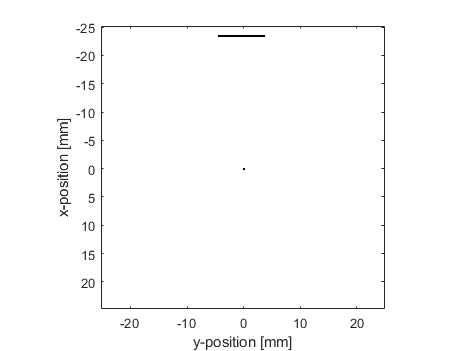

colormap(getColorMap);
ylabel('x-position [mm]');
xlabel('y-position [mm]');
axis image;

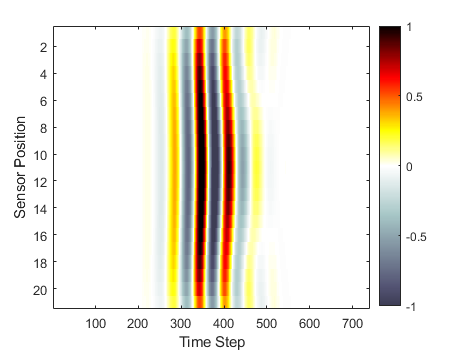


% plot the simulated sensor data
figure;
imagesc(sensor_data, [-1, 1]);
colormap(getColorMap);
ylabel('Sensor Position');
xlabel('Time Step');
colorbar;


kgrid.t_array

ans = 1.0e-04 *

         0    0.0008    0.0016    0.0023    0.0031    0.0039    0.0047    0.0055    0.0062    0.0070    0.0078    0.0086    0.0094    0.0102    0.0109    0.0117    0.0125    0.0133    0.0141    0.0148    0.0156    0.0164    0.0172    0.0180    0.0187    0.0195    0.0203    0.0211    0.0219    0.0227    0.0234    0.0242    0.0250    0.0258    0.0266    0.0273    0.0281    0.0289    0.0297    0.0305    0.0312    0.0320    0.0328    0.0336    0.0344    0.0352    0.0359    0.0367    0.0375    0.0383


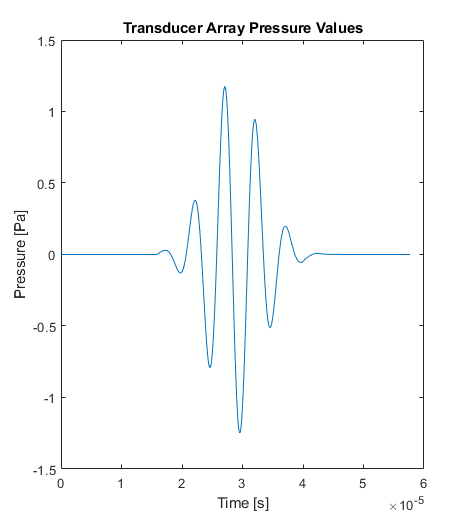


%plot pressure data at middle element
mid_element = round(num_elements/2);
figure;
plot(kgrid.t_array,sensor_data(mid_element, :));
xlabel('Time [s]');
ylabel('Pressure [Pa]');
title("Transducer Array Pressure Values")
scaleFig(1, 1.5);

cleanWave = sensor_data(mid_element, 220:400);
freqtest = A_getFrequency(cleanWave,kgrid.t_array(220:400))

freqtest = 2.0398e+05